# Airframe Model - One Degree of Freedom PD Model and Altitude Control

## Topic

This LiveScript continues with the development of your lesson on Airframes and includes the a simple altitude controller so that you can command your UAV to a desired altitude.

## Motivation

## Learning Objective

In this lesson you will develop a extend your simple one-degree-of-freedom model for altitude control so that you can command your UAV to a desired altitude.   You will modify your model of applied forces so that your UAV airframe can move to its desired altitude in a smooth and controlled fashion.

## Lesson

### Utilities Used in Lesson

clear;
addpath('utils');
params=sys_params;

## Where you are:  State-Space Representation of Equations of Motion with Drag and Feed-Forward

$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack +\frac{1}{m}\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
-\textrm{mg}
\end{array}\right\rbrack -k_d \sqrt{{\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
0\\
0\\
0\\
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
F_{\textrm{fwd}} 
\end{array}\right\rbrack \right\rbrace$   with $\left\lbrack \begin{array}{c}
x\left(0\right)\\
y\left(0\right)\\
z\left(0\right)\\
v_x \left(0\right)\\
v_y \left(0\right)\\
v_z \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 \\
v_{\textrm{x0}} \\
v_{\textrm{y0}} \\
v_{\textrm{z0}} 
\end{array}\right\rbrack$

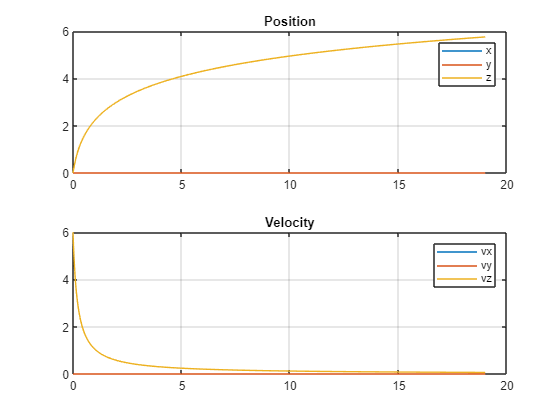

initial_x = 0;
initial_y = 0;
initial_z = 0;

v0= 6;    % m/s
thetad=0;
phid=0;
tmax = 19; 

tspan=[0,tmax];
theta=thetad*pi/180;  phi=phid*pi/180;     

[~,fxyz,mxyz,~,zdesired,kp,kv,~]=initializeParameters;

X0=[initial_x;initial_y;initial_z]; V0=[v0*sin(theta)*cos(phi);v0*sin(theta)*sin(phi);v0*cos(theta)];

w0=[X0;V0;zeros(6,1)];kd=0.05;
m=params.mass;g=params.gravity;ff=-m*g;
systemDerivative=@(t,w)dwdt(t,w,mxyz,fxyz,kd,ff,kp,kv,zdesired);

% Solve using ODE45
[ts,ws]=ode45(systemDerivative,tspan,w0); 
parametric_output3dof(ts,ws)

## Next Steps

With our model we are able to hover in place, but it was necessary that the initial velocity was zero and the vehicle was level with the coordinate system so that the feed-forward force exactly balanced the gravatational force.    The case where the vehicle is not level with the coordinate system will be left for the modules on the control system, as you have to understand more details about how the UAV actually flies, and in particular how its orientation interacts with the controls you want to give it.    For now, it is a logical next step for you to develop an enhancement to your model that allows you to start at one altitude (intial value of z) and move to another altitude and achieve a hover at this new position.

The detailed mathematics will be discussed in the controls modules but you can develop a heuristic appreciation for what needs to be done by considering a few cases.

- If you are at your desired altitude and your velocity is zero, the force you apply to stay there is precisely the feed-forward force.

- If you are below your desired altitude you need to apply an additional positive force to reach your desired altitude.

- If you are above yoru desired altitude, you need to reduce the force applied, by subtracting a force from the feed forward force to reach your desired altitude

- If you have a positive velocity as you approach your desired altitude, you need to reduce it to zero when you achieve your desired altitude.

- If you have a negative velocity as you approach your desired altitude, you need to increase it to zero when you acheive your desired altitude.

These facts lead you to the conclusion that one approach that can work is requires two additional forces.

$F_p =k_p \left(z_{\textrm{desired}} -z\right)$   and   $F_v =k_v \left(0-v_z \right)$ 

If you are at your desired altitude and your velocity is zero - then both of these forces are zero and you will achieve a successful hover.    If you need to adjust you altitude, $F_p$ applies a force to do so.    If you need to slow down $F_v$ applies a force to do so.  

As mentioned earlier, this will be discussed in more detail later.   For now, you can note that this is an introduction to a PD controller.

### Implementation of a PD Controller for Altitude

You can adjust these two coefficients and you will notice on the position output that if $k_p$ gets larger, then the UAV reaches the desired z- height faster.   You will also notice that if $k_v$ gets larger, the UAV will avoid overshooting the desired height.   By finding the right ratio of these two parameters you can achieved your desired UAV hover performance.    Since you are not applying any forces in either x or y, there is no impact to motion in those directions.

The resulting state-space equation becomes:

$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack +\frac{1}{m}\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
-\textrm{mg}
\end{array}\right\rbrack -k_d \sqrt{{\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
0\\
0\\
0\\
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
F_{\textrm{fwd}} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
F_{\textrm{pd}} 
\end{array}\right\rbrack \right\rbrace$   with $\left\lbrack \begin{array}{c}
x\left(0\right)\\
y\left(0\right)\\
z\left(0\right)\\
v_x \left(0\right)\\
v_y \left(0\right)\\
v_z \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 \\
v_{\textrm{x0}} \\
v_{\textrm{y0}} \\
v_{\textrm{z0}} 
\end{array}\right\rbrack$

with


$$F_{\textrm{pd}} =F_p +F_v$$


### Exercise

Adjust input parameters, desired altitude and PD control coefficients to explore performance.    What happens of you set kp and vary kd over a wide range?

clear;params=sys_params;
initial_x = 5;
initial_y = 5;
initial_z = 5;

v0= 0;    % m/s
thetad=0;
phid=0;

zdesired= 16; 
kp=  6;
kv= 2;
kd=kv;

F=@(t,Z)F_pd(t,Z,zdesired,kp,kd);

tmax = 7; 
tspan=[0,tmax];

theta=thetad*pi/180;  phi=phid*pi/180;                                 

X0=[initial_x;initial_y;initial_z]; V0=[v0*sin(theta)*cos(phi);v0*sin(theta)*sin(phi);v0*cos(theta)];
[~,fxyz,mxyz,~,zdesired,kp,kv,~]=initializeParameters

fxyz =      0
     0
     0


mxyz =      0
     0
     0


zdesired = 0

kp = 0

kv = 0

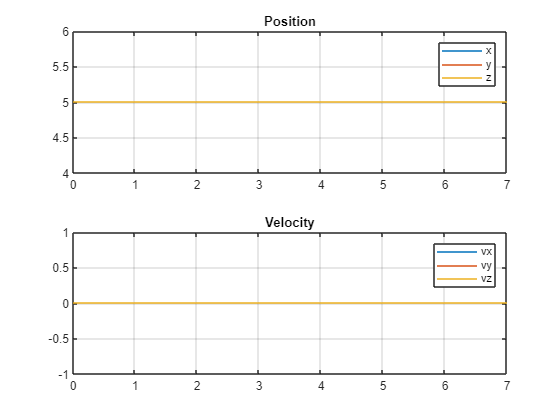


% Solve using ODE45
w0=[X0;V0;zeros(6,1)];kd=0.05;
m=params.mass;g=params.gravity;ff=-m*g;

systemDerivative=@(t,w)dwdt(t,w,mxyz,fxyz,kd,ff,kp,kv,zdesired);
[ts,ws]=ode45(systemDerivative,tspan,w0); 
parametric_output3dof(ts,ws)

### Exercise

Write you own function fpd, replacing the one provided above and compare your results.

% Your Function Goes here.





## Conclusion

In this lesson you extended your simple one-degree-of-freedom model for altitude control by introducing two new forces, one proportional to the distance to your desired altitude and one proportional ot your velocity.    With these, you were able to command your UAV to a desired altitude in a smooth and controlled fashion.